# Finite Precision Effects in IIR and FIR Filters (200 Points)

Dear Students, 

Welcome to Lab 5!

In all the previous labs, you have used **double precision floating point data types **(although we explicitly never mentioned it)**.**  Now, read: [https://in.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html](https://in.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) and answer the following: 

- What are the maximum and minimum numbers that you can represent using double precision floating point data types? 

            *ANSWER HERE: *The range for double precision floating point data type is:

                                        -1.79769e+308 to -2.22507e-308 and 2.22507e-308 to 1.79769e+308

                                         Maximum number: `1.79769e+308`

                                         Minimum number: `-1.79769e+308`

- Can you represent all the possible real numbers using the double precision data type? With what accuracy? 

          * ANSWER HERE: No. W*e cannot represent all possible real numbers using double precision data type. We can get an accuracy by using the eps(x) function, where the accuracy changes with changing x.

In practice, most of the time, we will need to implement filters using registers and processors which can store and process, respectively, a finite number of bits. Hence, we need to quantize the data and filter coefficients. In this lab, we will study how the filter characteristics get affected when we quantize them. 

### References: 

-  [https://spinlab.wpi.edu/courses/ece503_2014/week9.html](https://spinlab.wpi.edu/courses/ece503_2014/week9.html)                                                                                                                 

             **Please go through **[**https://spinlab.wpi.edu/courses/ece503_2014/9dot1.mp4,**](https://spinlab.wpi.edu/courses/ece503_2014/9dot1.mp4,)** without fail.** 

-  "A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall": Chapter 6, Section 6.1 and Section 7 of the 2nd Edition or Chapter 6, Section 7.1 and Section 8 of the 3rd Edition. 

### Learning Outcomes: 

At the end of the lab, you will be able to

- Explain 2's complement fixed point number representation

- Explain how the pole and zero locations, and the filter characteristics change in the IIR Filters due to coefficient quantization. 

- Explain how the zero locations and the filter characteristics change in the FIR filters due to coefficient quantization. 

## 2's-Complement Fixed Point Number Representation: 

Consider a register which stores $B+1$bits, $b_0 b_1,\ldots,b_{B-q}b_{B-q+1}b_B$, in the 2's-complement notation. The **decimal number** it represents (this is **what the processor sees) **is the** integer: **$-b_02^B+\sum_{i=1}^Bb_i2^{B-i}$. In the fixed-point representation, a register will not store the decimal or the binary point location. 

Now, as a programmer, you can **imagine **that the binary point is between $b_{B-q}$ and $b_{B-q+1}$, i.e, imagining $b_0 b_1,\ldots,b_{B-q\diamond}b_{B-q+1}b_B$, where $_\diamond$ denotes the binary point. In this case,  the number bits after binary points, called as the number of fractional bits, is $B-q$ bits. We can now interpret the number stored to be the decimal number:  $\hat{x}_B  = 2^{-(B-q)}\left(-b_02^B+\sum_{i=1}^Bb_i2^{B-i}\right)=2^{q}\left( -b_0+\sum_{i=1}^Bb_i2^{-i}\right)$.  With this imagined binary point, you as a programmer must take care of carrying out consistent arithmetic (addition and multiplication) operations, while the computer is interpreting the number as an integer.

- Suppose $\hat{x}_B = 1_\diamond 0101$in the 2's-complement format, what decimal number does it represent? 

             **ANS:** $-0\ldotp 6875$

- Suppose $\hat{x}_B = 0_\diamond 0101$in the 2's-complement format, what decimal number does it represent? 

**            ANS:** $0\ldotp 3125$

- Quantize 1/3 (in decimal) to 4 bits, using  (i) Rounding, and (ii) Truncation

                ** Rounding:** $0_\diamond 011$

                 **Truncation:** $0_\diamond 010$

## Finite Precision Effects in IIR Filters 

Let us design and quantize filter coefficients and analyse the impact of quantization on filter characteristics. We are using the example given in [https://spinlab.wpi.edu/courses/ece503_2014/9-3coefficient_quantization_iir.pdf](https://spinlab.wpi.edu/courses/ece503_2014/9-3coefficient_quantization_iir.pdf)

Our requirements are given below. 

Fpass = 0.2; % Passband Frequency
Fstop = 0.25; % Stopband Frequency
Apass = 1; % Passband Ripple (dB)
Astop = 60; % Stopband Attenuation (dB)
match = 'both';

  Now, we can either go the  *filterDesigner *to design the filter or we can design the filter using the code below. Look at [https://in.mathworks.com/help/dsp/ref/fdesign.lowpass.html](https://in.mathworks.com/help/dsp/ref/fdesign.lowpass.html) for more details on this method. 

h = fdesign.lowpass('Fp,Fst,Ap,Ast',Fpass, Fstop, Apass, Astop); % Create a lowpass filter specification object
Hd = design(h, 'ellip', 'MatchExactly', match);  % 
[b, a] = tf(Hd);             % Extract the filter coef

% Display as a table
Coef_Double_Prec = table(b', a');
Coef_Double_Prec.Properties.VariableNames = {'b','a'};
Coef_Double_Prec.Properties.Description = 'The filter coefficients  in double-precision floating point format'

Coef_Double_Prec = 8×2 table
        b            a    
    __________    ________

      0.002567           1
    -0.0063435      -5.676
     0.0086181      14.495
    -0.0036387     -21.459
    -0.0036387      19.833
     0.0086181     -11.425
    -0.0063435      3.7981
      0.002567    -0.56257


Now assume that we have $B+1 = 8$bit register to store and implement the filter. Observe the coefficients, $b$ and $a$. 

- Can you represent all the coefficients in 8 bits?   ANS:  No,

- What is the dynamic range of denominator coefficient, $a$?  That is, what is $\frac{\max\{|a|\}}{\min\{|a|\}}$?

            ANS: **38.1434**

### One-Shot Direct-Form Realizations  (75 Points)

Now, let us quantize these coefficients to $8$bit 2's complement format. In the below, we will assume that all the elements in $a$ and $b$ will be represented by same number of fractional bits (can be different for $a$ and $b$). We will first identify the minimum number of bits required for representing the non-fractional part of the  maximum number: In this case, there will not be saturation of any of the coefficients. However, there will be huge rounding errors. 

B_qa = ceil(log2(max(abs(a(2:end)))));   % FILL IN THE BLANKS: Compute the minimum number of bits required for representing the
% non-fractional part of the maximum value in the "a" coefficients. 
B_qb = ceil(log2(max(abs(b))));  % FILL IN THE BLANKS: Compute the minimum number of bits required for representing the
% non-fractional part of the maximum value in the "b" coefficients. 

B = 7;   % 8 bit register is available. So B = 7 (see the previous section about 2's complement notation)   
qa = B - B_qa; % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "a" coefficients
qb = B - B_qb;  % FILL IN THE BLANKS:  Number of bits available for denoting the fraction part of "b" coefficients

if qa > B
    qa = B;
end

if qb > B
    qb = B;
end

aHat = round(a*2^qa)/2^qa; % FILL IN THE BLANKS: Quantized "a"
bHat = round(b*2^qb)/2^qb;  % FILL IN THE BLANKS: Quantized "b"
Coef_8bit_fixed_point = table(b', bHat', bHat'*2^qb, a', aHat', aHat'*2^qa);
Coef_8bit_fixed_point.Properties.VariableNames = {'b','bHat','bHat for Computer'  ,'a', 'aHat','aHat for Computer'};
Coef_8bit_fixed_point.Properties.Description = 'The filter coefficients in double-precision floating point format'

Coef_8bit_fixed_point = 8×6 table
        b            bHat       bHat for Computer       a        aHat     aHat for Computer
    __________    __________    _________________    ________    _____    _________________

      0.002567             0            0                   1        1             4       
    -0.0063435    -0.0078125           -1              -5.676    -5.75           -23       
     0.0086181     0.0078125            1              14.495     14.5            58       
    -0.0036387             0            0             -21.459    -21.5           -86       
    -0.0036387             0            0              19.833    19.75            79       
     0.0086181     0.0078125            1             -11.425    -11.5           -46       
    -0.0063435    -0.0078

Now, obtain the frequency response and the pole-zero plot of the original and quantized filters: 

- Frequency response of the original filter is:

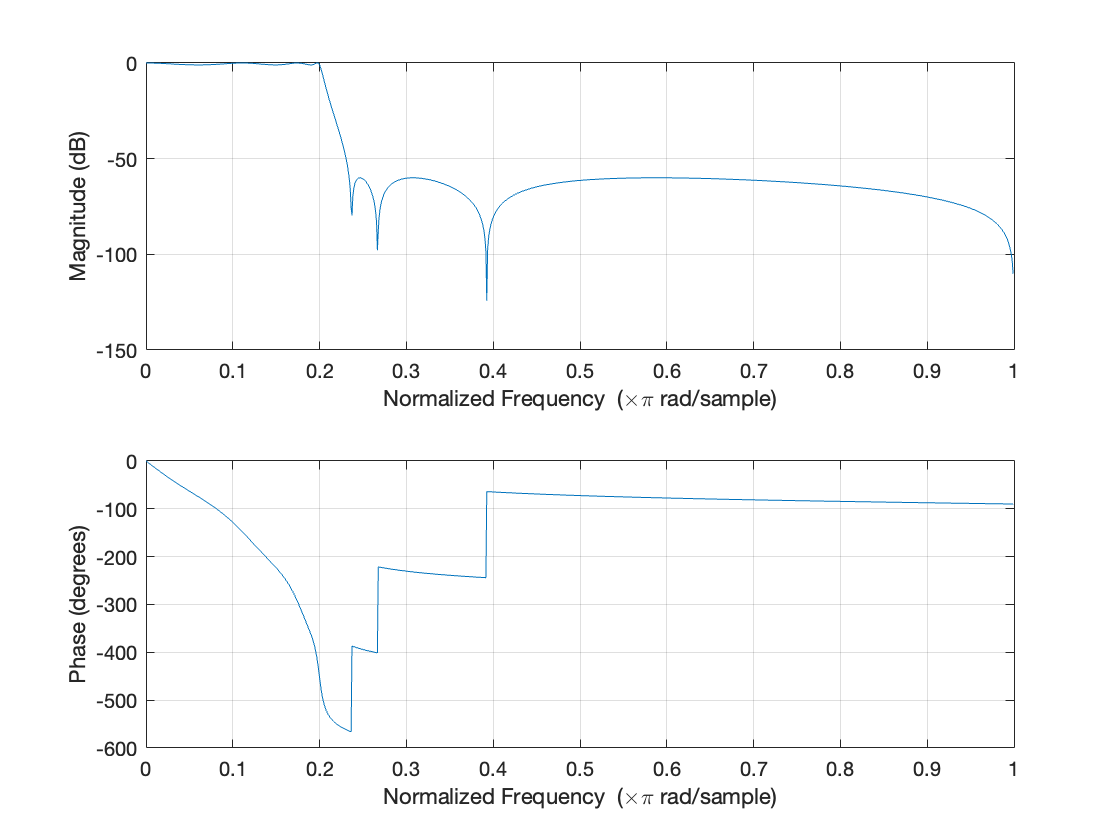

% ENTER YOUR CODE HERE
freqz(b,a,1024);

- Pole-zero plot of the original filter is:

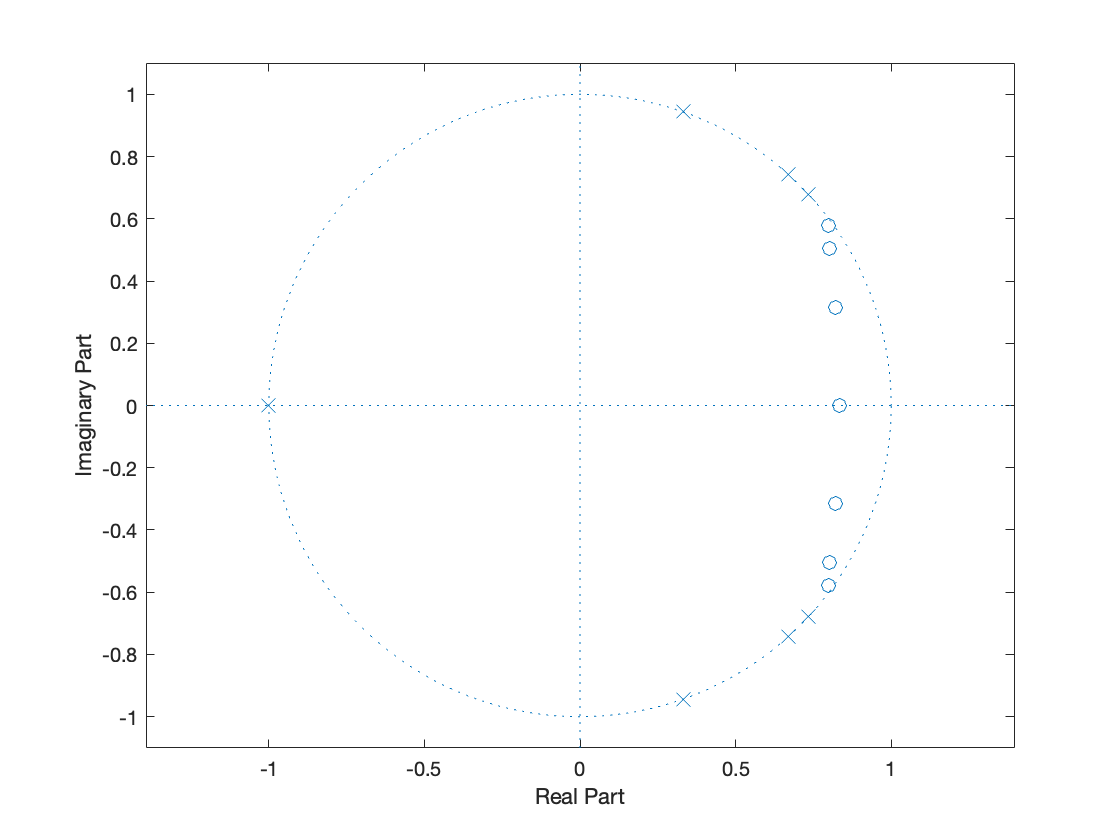

% ENTER YOUR CODE HERE
zplane(a,b);

- Frequency response of the quantized filter is:

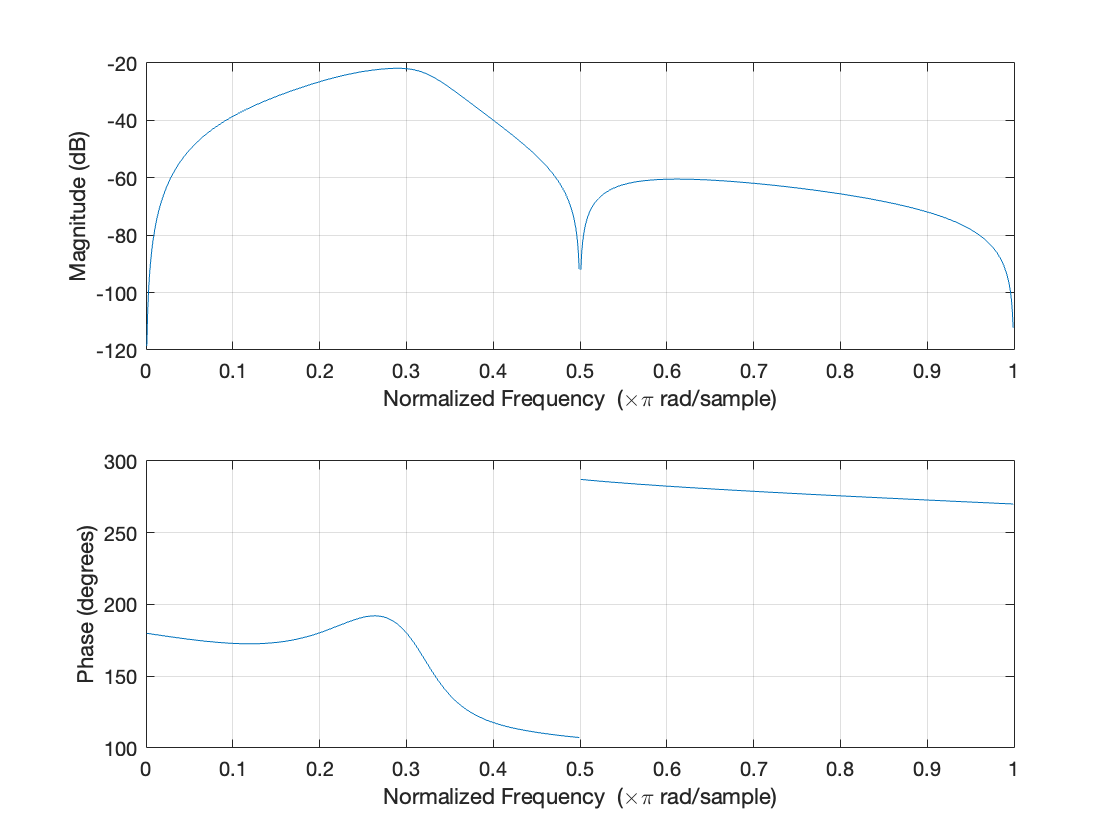

% ENTER YOUR CODE HERE
freqz(bHat,aHat,1024);

- Pole-zero plot of the quantized filter is: 

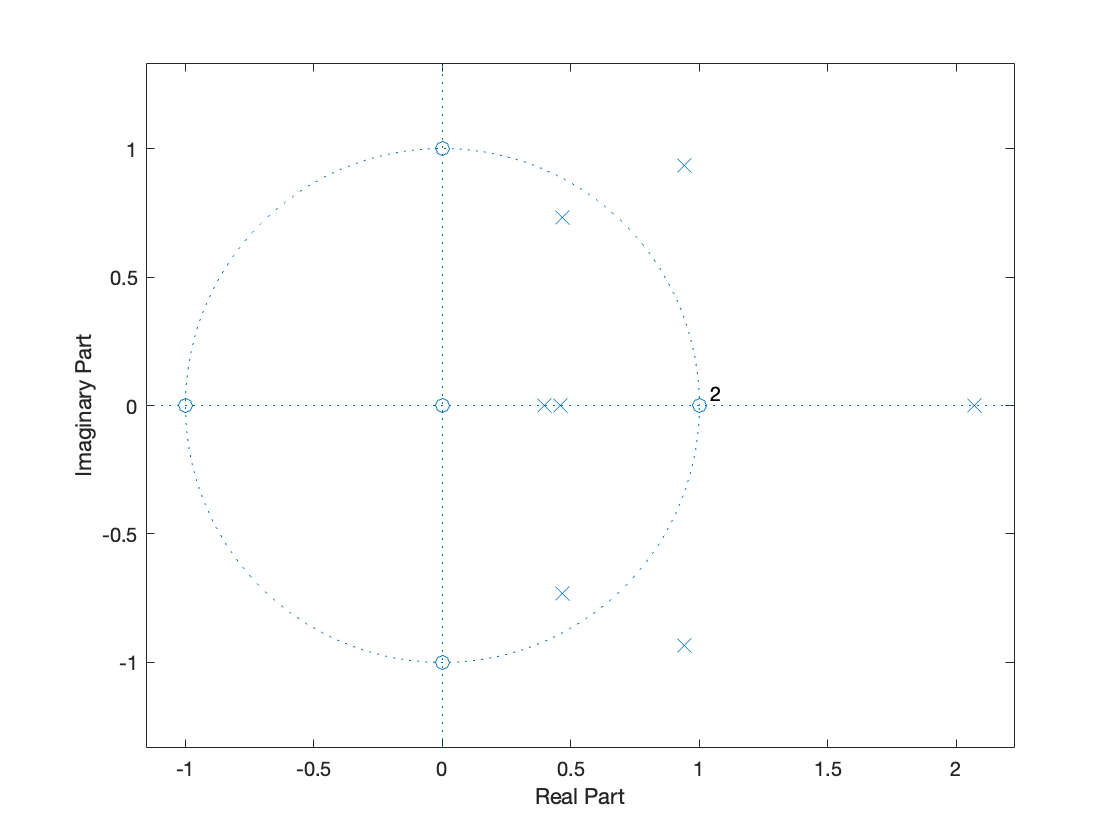

% ENTER YOUR CODE HERE
[P,Z] = pzmap(bHat,aHat);
zplane(Z,P);

- Comment on the quantized coefficients. Which quantization method did you use?  

          * ANSWER HERE: *We see the quantized coefficients using 8 bits approximate the values of **a **very well, but the approximated values of **b **have significant errors (as 8 bits are not sufficient to quantize those numbers). We used rounding method as it gives a lower error as compared to truncation.

- Is the new filter with quantized coefficients stable? How does the frequency response compare with the original filter? 

          * ANSWER HERE: *No, the new filter with quantization coefficients is not stable. The quantized filter gives a fair approximation for the original filter at higher frequencies, but for the lower frequencies we see a lot of distortion.

- (True/False, If false, correct the statement): Each quantized numerator coefficient changes only a single zero.  

          * ANSWER HERE: False, *Each quantized numerator coefficient changes only a multiple zeros.

- (True/False, If false, correct the statement): Each quantized denominator coefficient changes only a single pole.  

           * ANSWER HERE: False, *Each quantized numerator coefficient changes only a multiple poles.

- (True/False, If false, correct the statement): Quantizing the numerator coefficients will never make a filter unstable.  

          * ANSWER HERE: False, *Quantizing the numerator coefficients can make a filter unstable.

### Cascade Form Realizations: (75 Points)

We called the previous subsection as "One-Shot Direct-Form Realizations". Why is it justified? (Think of how we implement the direct form structures once the coefficients are designed)

          * ANSWER HERE: *In this subsection, we will look at how the quantization of filter coefficients will affect the filter response if we adopt cascade form realization. Specifically, we will focus on the second-order-sections. 

In this subsection, we will look at how the quantization of filter coefficients will affect the filter response if we adopt cascade form realization. Specifically, we will focus on the second-order-sections. 

How many second order sections does the filter in the above subsection require?

  * ANSWER HERE: The filter in above subsection requires 4 second order sections.*

- Obtain $b $ and $a$ coefficients of each of the second order sections. (Use [tf2sos](https://in.mathworks.com/help/signal/ref/tf2sos.html))

[sosMatrix, gain] = tf2sos(b,a) %FILL IN THE BLANKS:

sosMatrix =     1.0000    1.0000         0    1.0000   -0.8345         0
    1.0000   -0.6625    1.0000    1.0000   -1.6416    0.7738
    1.0000   -1.3375    1.0000    1.0000   -1.6032    0.8957
    1.0000   -1.4712    1.0000    1.0000   -1.5967    0.9726


gain = 0.0026


% Coefficients of the first SOS are
b1 = [1 1 0];
a1 = [1 -.8345 0];

% In the below, write down bi and ai for the ith SOS (depending on how many SOS are there)

b2 = [1 0.6625 1];
a2 = [1 -1.6416 0.7738];
b3 = [1 -1.3375 1];
a3 = [1 -1.6032 0.8957];
b4 = [1 -1.4712 1];
a4 = [1 -1.5967 0.9726];

% FILL IN THE BLANKS



- What is the dynamic range of the coefficients now? Are they greater or smaller compared to those in Direct-Form Realizations

            * ANSWER HERE: *

            For denominator coefficients dynamic ranges are:

            inf

            2.12

            1.789

            1.641

- Now quantize (with B=7) each section separately. 

            * ANSWER HERE: *

%% ENTER YOUR CODE HERE
[b1hat,a1hat]=rounder(b1,a1);
[b2hat,a2hat]=rounder(b2,a2);
[b3hat,a3hat]=rounder(b3,a3);
[b4hat,a4hat]=rounder(b4,a4);

- Obtain the overall filter response of the above filter where each SOS section is quantized separately. 

%% ENTER YOUR CODE HERE
new_sos=[b1hat a1hat;b2hat a2hat;b3hat a3hat;b4hat a4hat]

new_sos =     1.0000    1.0000         0    1.0000   -0.8359         0
    1.0000    0.6641    1.0000    1.0000   -1.6406    0.7812
    1.0000   -1.3438    1.0000    1.0000   -1.6094    0.8906
    1.0000   -1.4688    1.0000    1.0000   -1.5938    0.9688


- Obtain the overall pole-zero plot of the  above filter where each SOS section is quantized separately. 

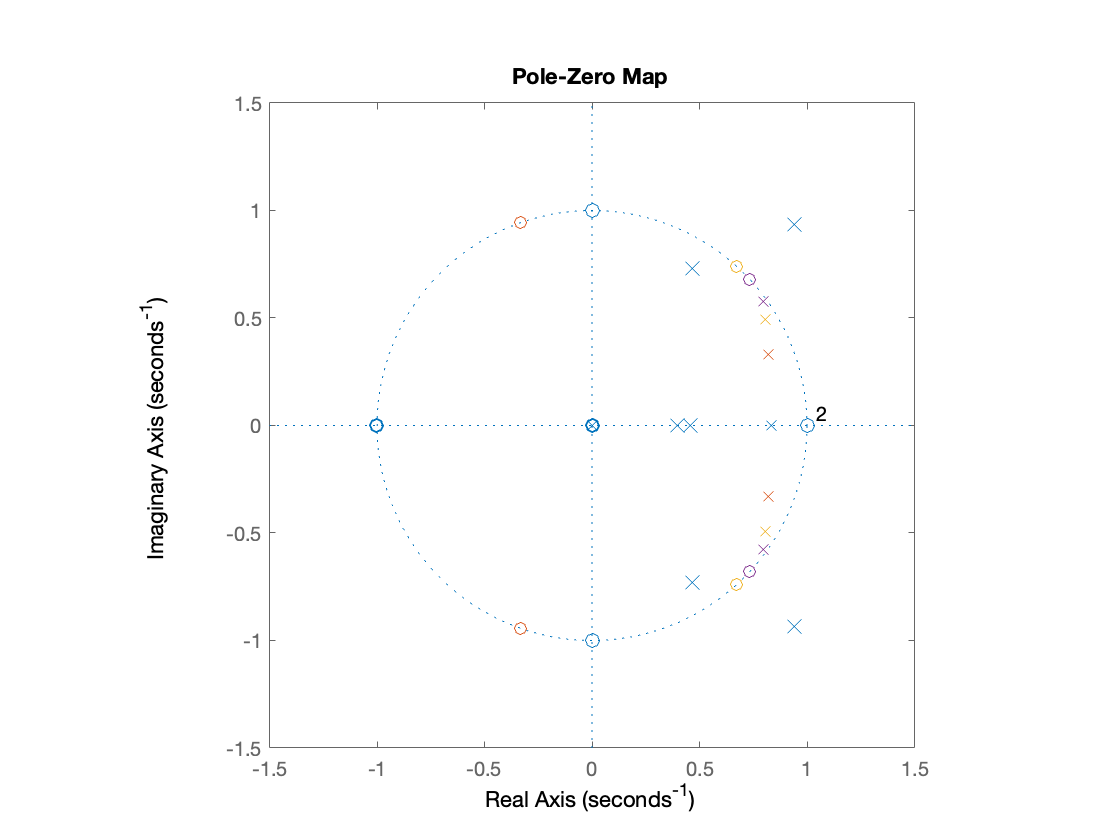

 %% ENTER YOUR CODE HERE
hold on 
pzmap(b1hat,a1hat)
pzmap(b2hat,a2hat)
pzmap(b3hat,a3hat)
pzmap(b4hat,a4hat)
xlim([-1.5 1.5])
ylim([-1.5 1.5])
hold off

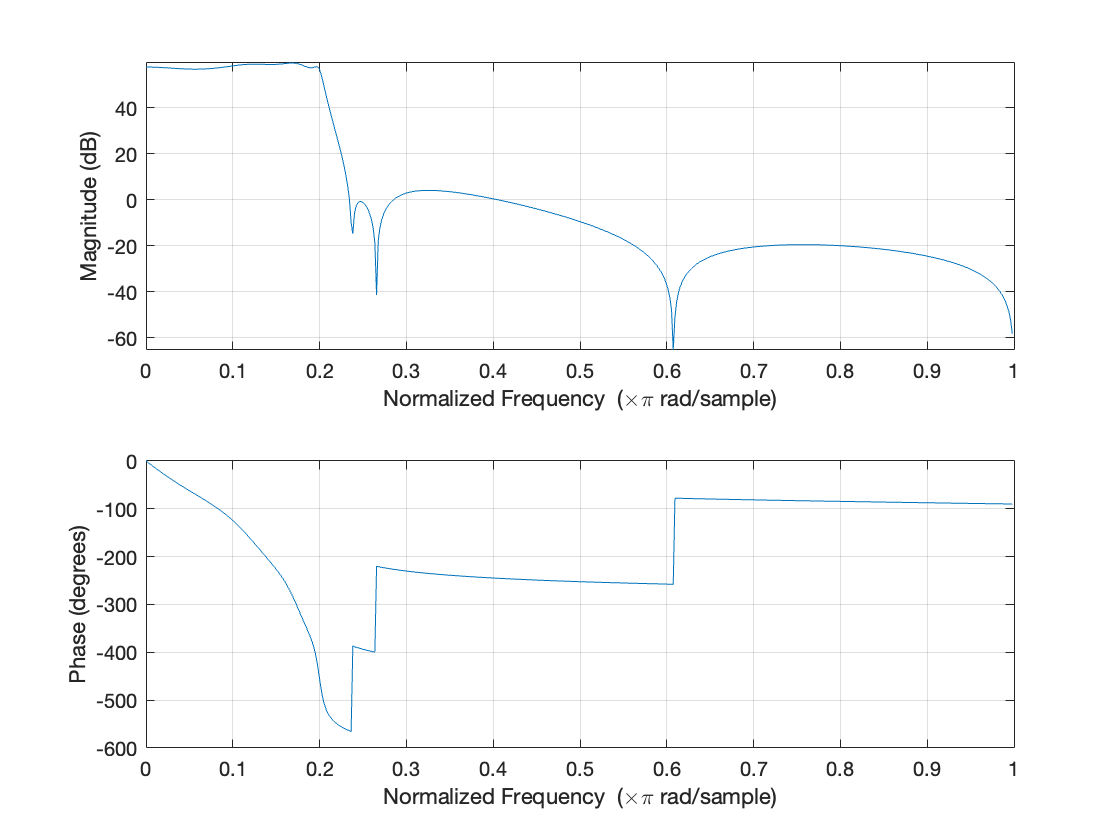

freqz(new_sos);

- How does the filter response in the quantized Cascade Form compare with that in the One-Shot Direct Form realizations? 

            * ANSWER HERE: For* cascade form, the filter behaves a lot more like the original filter, while in the one-shot direct form realizations there are many deviations from the original filter behaviour. 

- How does the pole-zero locations in the quantized Cascade Form compare with that in the One-Shot Direct Form realizations? 

  *            ANSWER HERE: *In the quantized cascade form, it is noticed that the pole-zero locations more closely match with the original filter's poles and zeros, while we notice significant differences in the pole-zero plot of one shot direct form realization.

### Possible Pole Locations in Second-Order Section - Scope for Improvements

In this subsection, we will see, how we can improve implementation of each SOS section. Now, refer to [https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf](https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf)

Note that a single SOS (assuming only poles are present), can be represented as below: 


$$H(z) = \frac{1}{1+Kz^{-1}+Lz^{-2}}$$


Suppose $K$ and $L$ are represented with $B+1=8$ bits and $q_a = 4$ (number of bits used for representing fractional part) 

Now, the possible values $K$and $L$ can take are: 

min = -128/16; % min possible using 8 bits
max = 127/16; % max possible using 8 bits
step = 1/16; 
K  = min:step:max;
L = min:step:max;

Now, plot all the possible pole locations for the above values of $K$and $L$, along with the unit circle  

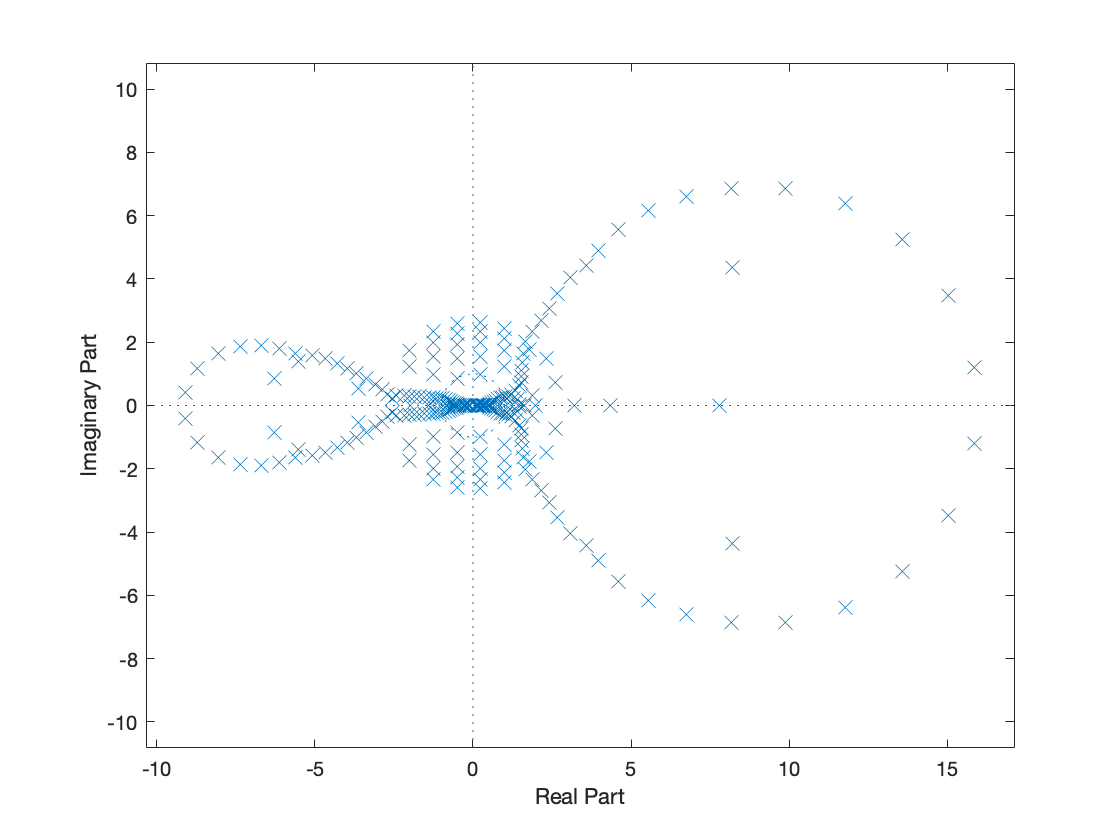

len = length(K);
temp = 1;
steps = 24; % plotting only a subsample as we cannot plot all the values
for i = 1:steps:len
    for j = 1:steps:len
        b = [1,K(i),L(j)];
        temp = temp*tf(1,b);
    end
end

[Ph,Zh] = pzmap(temp);
zplane(Zh,Ph)

- What are your observations  on the pole locations? Are they evenly spaced? What does this mean in terms of realizing low and high-pass filters when the coefficients are quantized. 

*            ANSWER HERE: No, they are not evenly spaced, if we have a 8 bit system these are all the options of poles possible.*

Now consider the SOS in the Coupled-Form, which appears on Slide 4 of  [https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf.](https://spinlab.wpi.edu/courses/ece503_2014/9-5pole_locations.pdf.) Its system function, 

$H(z) = \frac{\beta}{1-2\alpha z^{-1}+(\alpha^2+\beta^2)z^{-2}}$.

Now, suppose $\alpha$ and $\beta
$ are represented with $B+1=8$ bits and $q_a = 4$ (number of bits used for representing fractional part). The possible values $\alpha$ and $\beta
$ can take are: 

min = -128/16;
max = 127/16;
step = 1/16;
alpha  = min:step:max;
beta = min:step:max;

Now, plot all the possible pole locations for the above values of $\alpha$ and $\beta
$, along with the unit circle  

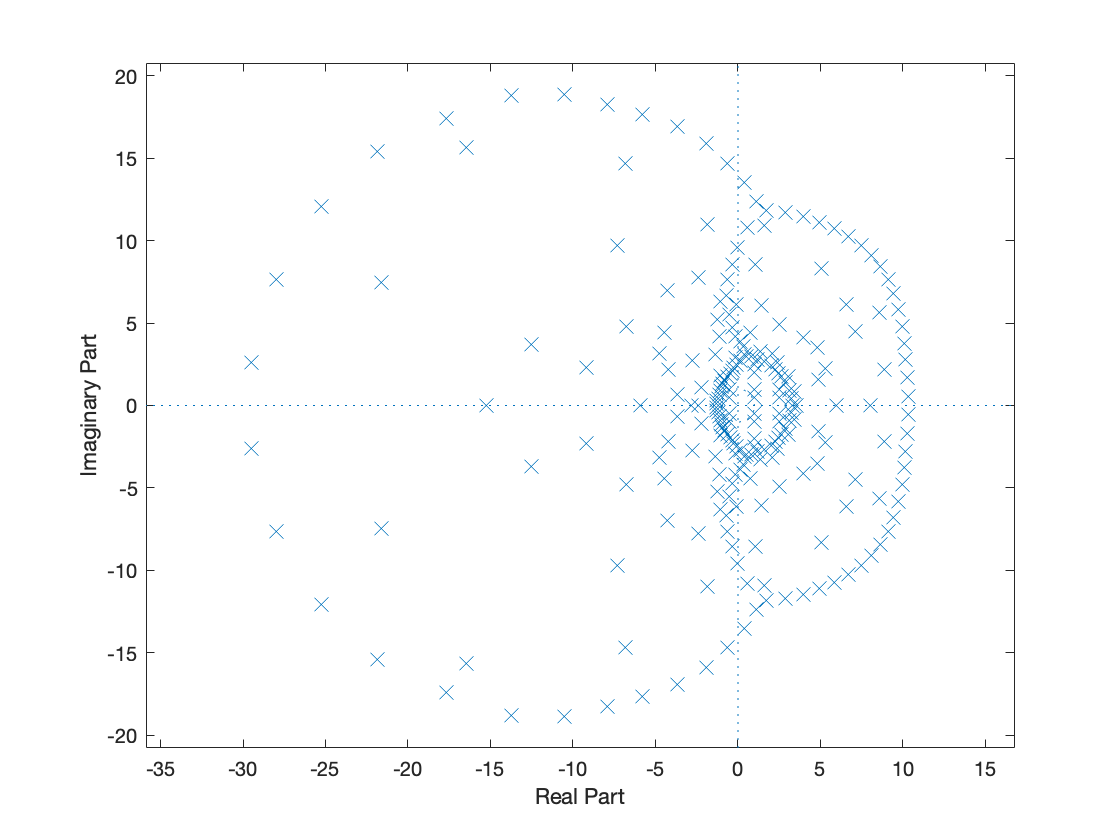

% ENTER YOUR CODE HERE.
len1 = length(alpha);
temp = 1;
steps = 24;
for i = 1:steps:len1
    for j = 1:steps:len
        b = [1,-2*alpha(i),(alpha(i)^2+beta(j)^2)];
        temp = temp*tf(1,b);
    end
end
[Ph1,Zh1] = pzmap(temp);
zplane(Zh1,Ph1)

- What are your observations  on the pole locations? Are they evenly spaced? What does this mean in terms of realizing the low and high-pass filters when the coefficients are quantized. 

*            ANSWER HERE: No, the poles are not evenly spaced.If we have a 8 bit system these are all the options of poles possible.*

## Finite Precision Effects in FIR Filters 

Design a linear-phase FIR filter with the following specifications (Use any method): 

- What is the impulse response of the FIR filter you designed? 

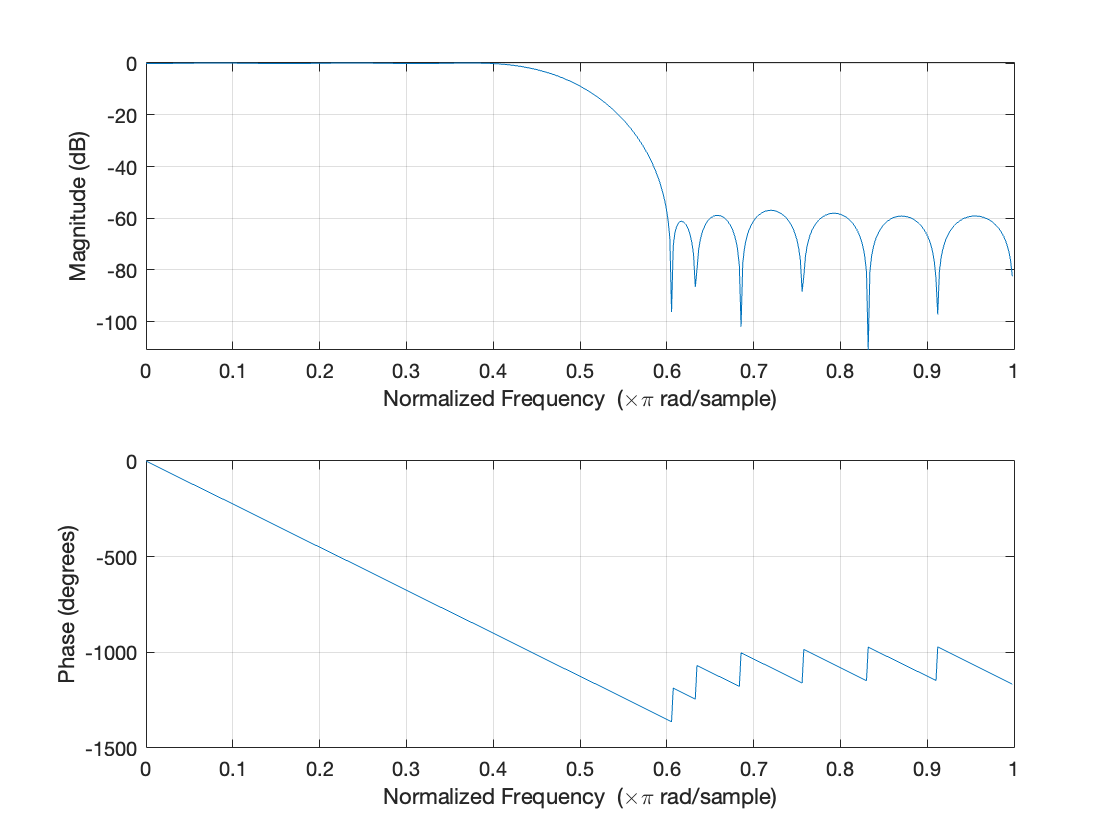

%obtained from Filter Designer
h  = [-0.0027;
   -0.0077;
   -0.0013;
    0.0126;
    0.0052;
   -0.0223;
   -0.0135;
    0.0377;
    0.0305;
   -0.0663;
   -0.0735;
    0.1574;
    0.4378;
    0.4378;
    0.1574;
   -0.0735;
   -0.0663;
    0.0305;
    0.0377;
   -0.0135;
   -0.0223;
    0.0052;
    0.0126;
   -0.0013;
   -0.0077;
   -0.0027;];

freqz(h');

### One-Shot Director Form Realizations  (50 Points)

- Now, quantize the impulse response to  8 bits (B=7). 

hHat = rounderfir(h') % Quantized h 

hHat =          0   -0.0078         0    0.0156    0.0078   -0.0234   -0.0156    0.0391    0.0312   -0.0625   -0.0703    0.1562    0.4375    0.4375    0.1562   -0.0703   -0.0625    0.0312    0.0391   -0.0156   -0.0234    0.0078    0.0156         0   -0.0078         0


- Now plot the frequency response of the original filter and the quantized filter. 

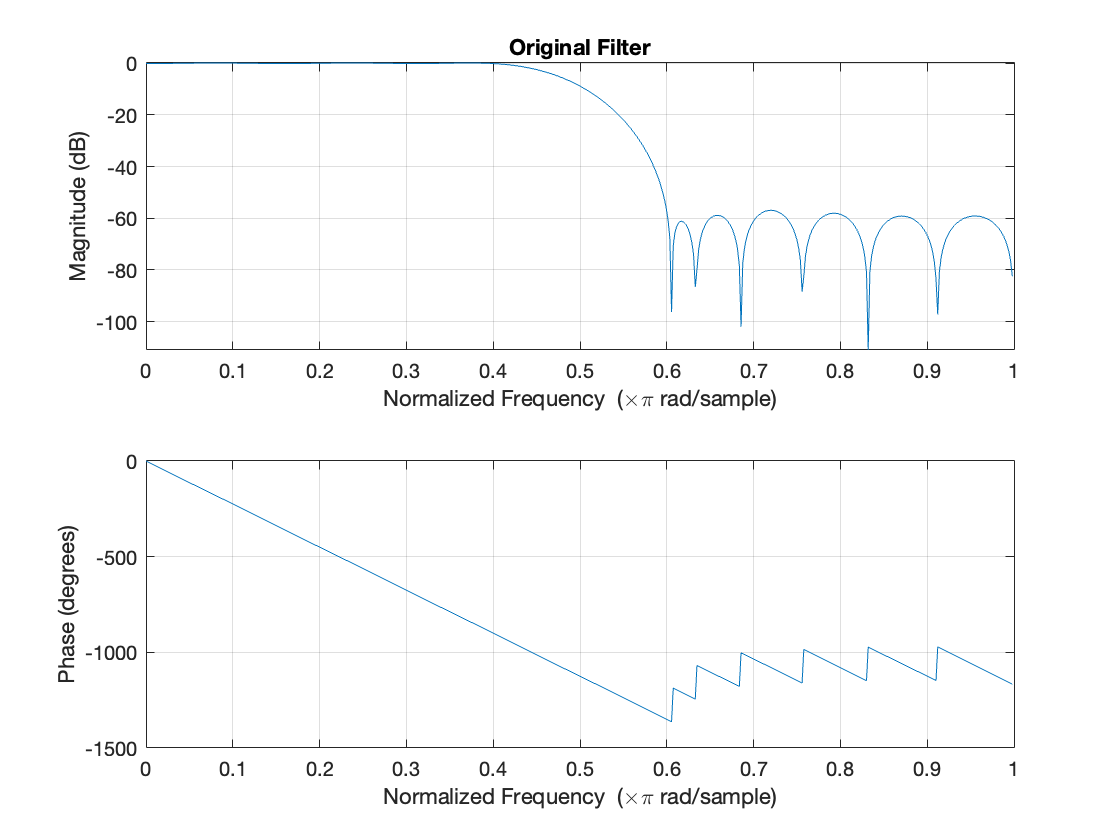

% Magnitude and Phase Response
freqz(h,1)
title('Original Filter');

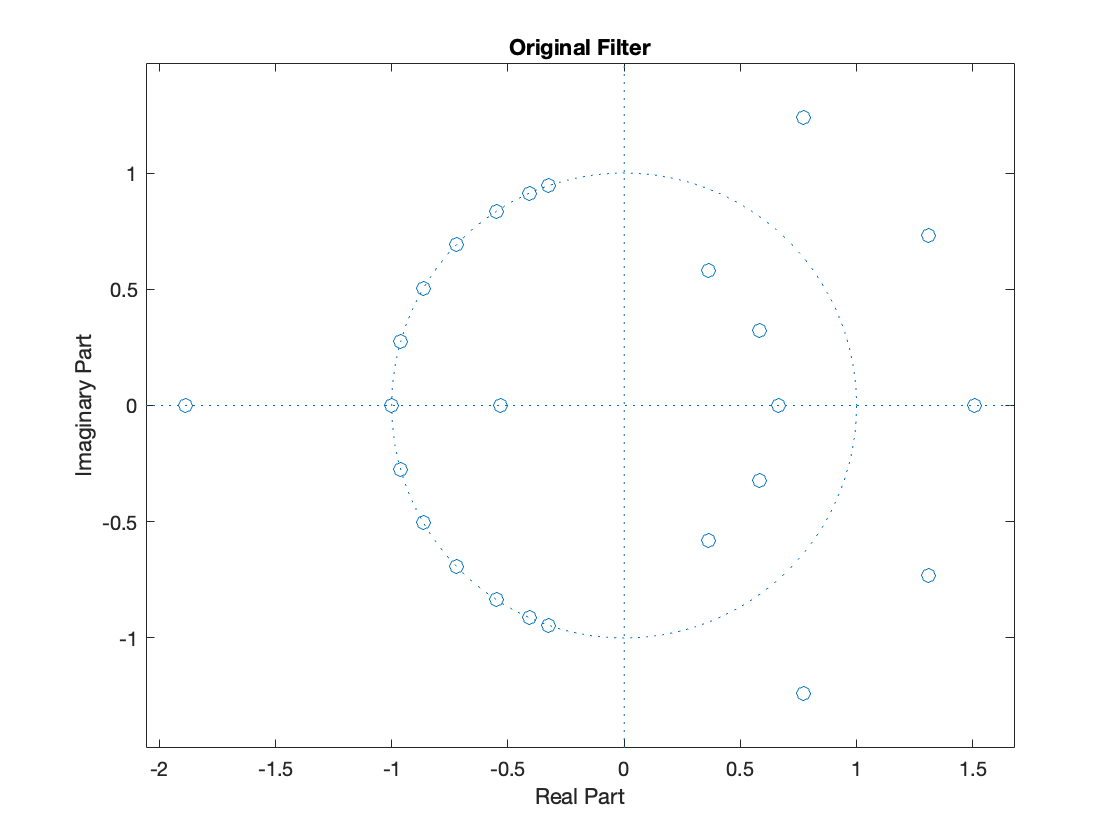

H = tf(h',1);
[P,Z] = pzmap(H);
zplane(Z,P)
title('Original Filter');

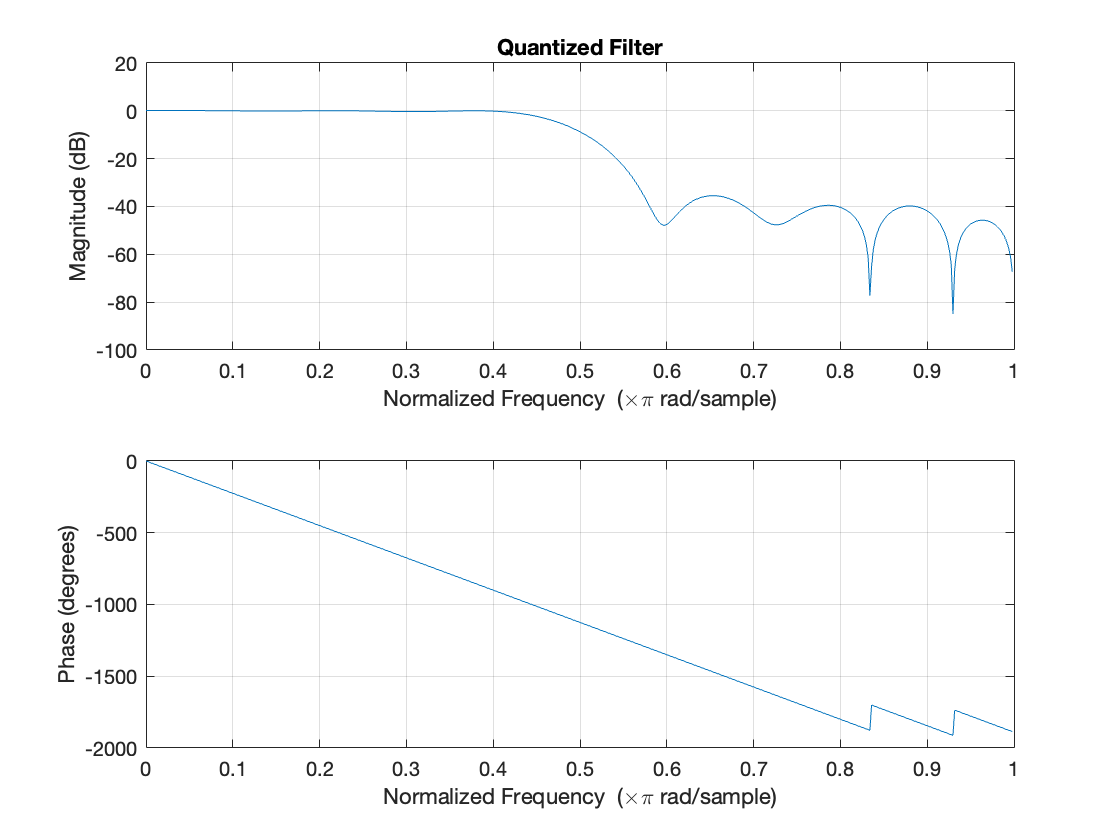

freqz(hHat,1)
title('Quantized Filter');

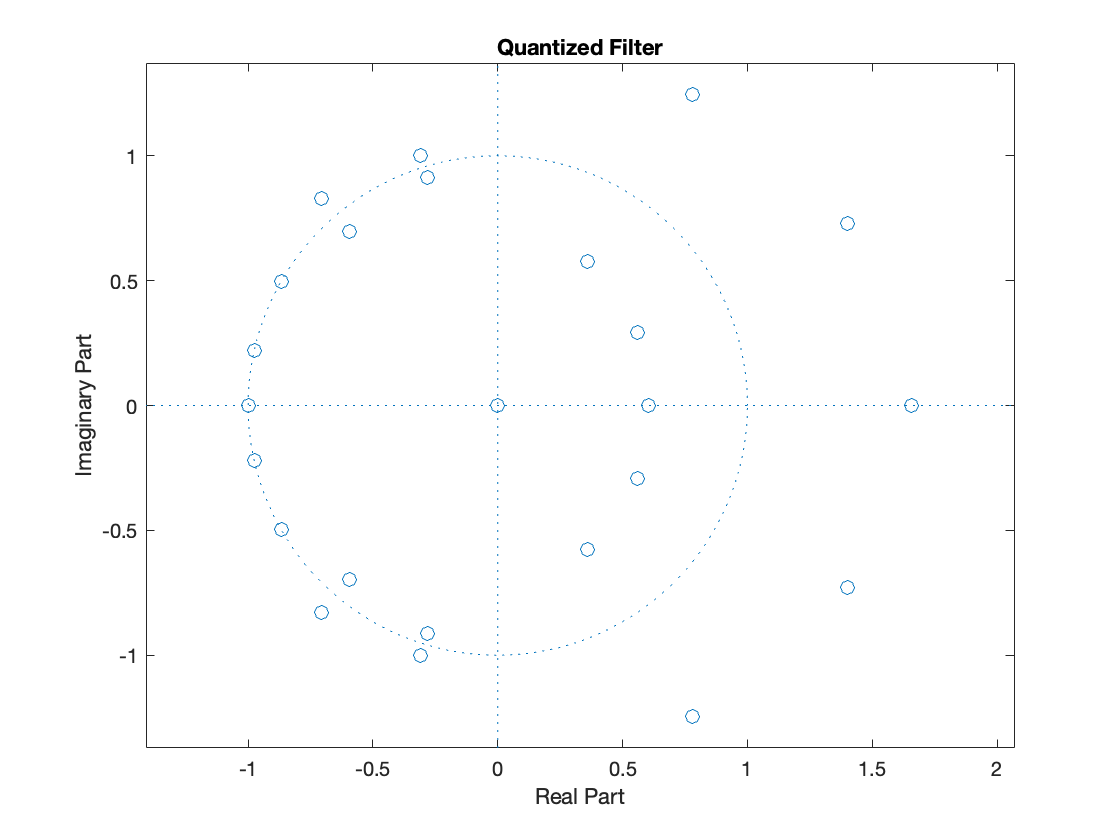

H = tf(hHat,1);
[P,Z] = pzmap(H);
zplane(Z,P)
title('Quantized Filter');

Now answer the following: 

- How do the frequency responses of the original and quantized filters compare with each other? 

*            ANSWER HERE: *The stopband gain does not follow the specifications in case of quantized filter, that is, the magnitude is greater than -60dB. The original filter was equiripple in the passband, while the quantized filter has ripples of varying amplitude.

- How do the locations of the zeros of the original and quantized filters compare with each other? 

*            ANSWER HERE: From the pole-zero plot we can infer that the plots are different for both the original FIR filter and the quantized FIR filter.*

- Does the quantized filter maintain its linear phase behavior? 

*            ANSWER HERE: *Yes, the quantized filter maintain its linear phase behavior.

### Cascaded Form Realizations (Optional)

Study Section 7.6 of the 2nd Edition or Section 8.6 of the 3rd Edition in Chapter 6 of the Textbook and mention how can we achieve linear-phase when using SOS for implementing an FIR filter. 

In the next lab, we will explore the actual implementation of filters with quantized coefficients and input data. 

function [bhat,ahat] = rounder(b,a)
    nonfraca = ceil(log2(max(abs(a))));
    nonfracb = ceil(log2(max(abs(b))));
    B = 7; % we have B+1 total bits, including sign
    qa = B-nonfraca; % fractional bits for denominator
    qb = B-nonfracb; % fractional bits for numerator
    if qa > B
        qa = B;
    end

    if qb > B
        qb = B;
    end

    ahat = round(a.*2.^qa)./2.^qa; % quantized denominator
    bhat = round(b.*2.^qb)./2.^qb; % quantized numerator
end

function [ahat] = rounderfir(a)
nonfraca = ceil(log2(max(abs(a))));
B = 7; % we have B+1 total bits, including sign
qa = B-nonfraca; % fractional bits for denominator
if qa > B
    qa = B;
end
ahat = round(a.*2.^qa)./2.^qa; % quantized denominator
end

## Thank you!